
syms x y
u(x,y) = x*y*(1-x)*(1-y)

$$u(x, y) = x\,y\,\left(x-1\right)\,\left(y-1\right)$$

f = -diff(u,x,2) -diff(u,y,2)

$$f(x, y) = -2\,x\,\left(x-1\right)-2\,y\,\left(y-1\right)$$

g0 = 0

g0 = 0

gy = diff(u,y)

$$gy(x, y) = x\,y\,\left(x-1\right)+x\,\left(x-1\right)\,\left(y-1\right)$$

gx = diff(u,x)

$$gx(x, y) = x\,y\,\left(y-1\right)+y\,\left(x-1\right)\,\left(y-1\right)$$

a1 = subs(gy, y, 1)

$$a1(x, y) = x\,\left(x-1\right)$$

a2 = subs(-gy, y,0)

$$a2(x, y) = x\,\left(x-1\right)$$

a3 = subs(gx,y, 1)

$$a3(x, y) = 0$$

%plot 3d
[X,Y] = meshgrid(0:0.1:1,0:0.1:1)

X =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.00

Y =          0         0         0         0         0         0         0         0         0         0         0
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000
    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000
    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000
    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000
    0.8000    0.8000    0.8000    0.8000    0.8000    0.8000    0.8000    0.8000    0.8000    0.8000    0.80

Z = X.*Y.*(X - 1).*(Y - 1)

Z =          0         0         0         0         0         0         0         0         0         0         0
         0    0.0081    0.0144    0.0189    0.0216    0.0225    0.0216    0.0189    0.0144    0.0081         0
         0    0.0144    0.0256    0.0336    0.0384    0.0400    0.0384    0.0336    0.0256    0.0144         0
         0    0.0189    0.0336    0.0441    0.0504    0.0525    0.0504    0.0441    0.0336    0.0189         0
         0    0.0216    0.0384    0.0504    0.0576    0.0600    0.0576    0.0504    0.0384    0.0216         0
         0    0.0225    0.0400    0.0525    0.0600    0.0625    0.0600    0.0525    0.0400    0.0225         0
         0    0.0216    0.0384    0.0504    0.0576    0.0600    0.0576    0.0504    0.0384    0.0216         0
         0    0.0189    0.0336    0.0441    0.0504    0.0525    0.0504    0.0441    0.0336    0.0189         0
         0    0.0144    0.0256    0.0336    0.0384    0.0400    0.0384    0.0336    0.0256    0.0144        

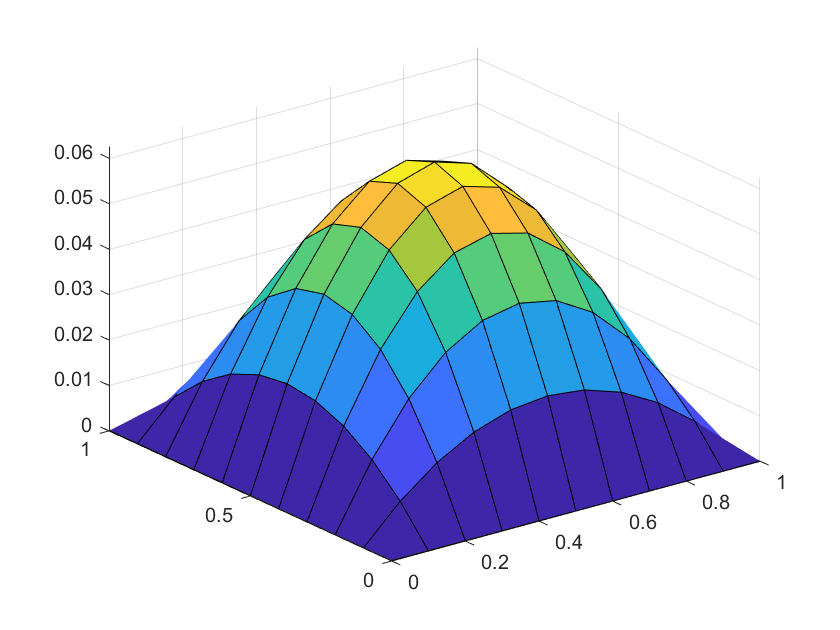

surf(X,Y,Z)